# Visualizacion de trayectoria

Revision de las trayectoiras generadas a partir de los vectores articulares 

dhparams = [0, 0, 18, 0]; %% Descripción de los eslabones 

L(1) = Link(dhparams); 
L(2) = Link(dhparams);

r = SerialLink("name", "2R", L);  % definicion del robot

ws = [-40, 40, -40, 40, 0, 30]; 
q = [0, 0]

q =      0     0


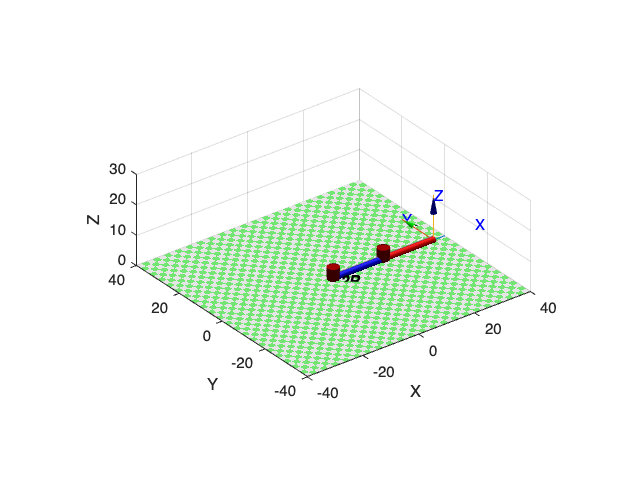

r.plot(q, "workspace", ws); %% Espacio de trabajo revisado

## Dibujo trébol

Se define la cinemática directa del mecanismo simbolicamente para evaluar. 

rsym = r.sym

 
rsym = 
 
2R:: 2 axis, RR, stdDH, slowRNE, Symbolic                        
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|         18|          0|          0|
|  2|         q2|          0|         18|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


syms theta1 theta2
pos = rsym.fkine([theta1, theta2]).t

$$pos = \left(\begin{array}{c} 18\,\cos\left(\theta_{1}+\theta_{2}\right)+18\,\cos\left(\theta_{1}\right)\\ 18\,\sin\left(\theta_{1}+\theta_{2}\right)+18\,\sin\left(\theta_{1}\right)\\ 0 \end{array}\right)$$

## Perfiles articulares

t = sim_theta1.Time; 

% Articulaciones 
t1 = sim_theta1.Data

t1 =     2.0073
    1.9995
    1.9932
    1.9880
    1.9837
    1.9800
    1.9763
    1.9722
    1.9670
    1.9601


t2 = sim_theta2.Data

t2 =    -2.3656
   -2.3796
   -2.3947
   -2.4111
   -2.4287
   -2.4475
   -2.4676
   -2.4887
   -2.5108
   -2.5335


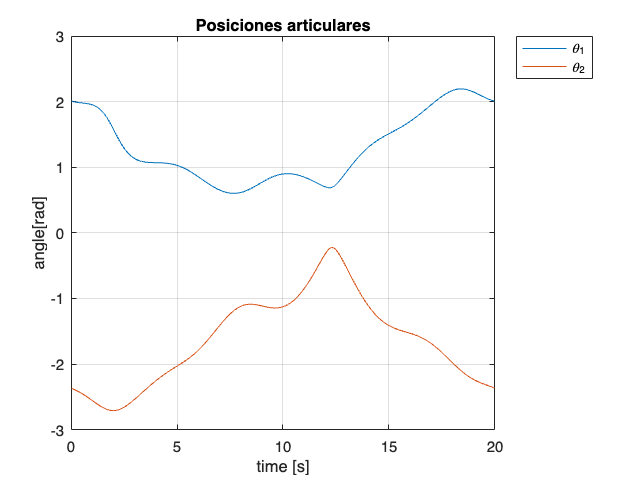


plot(t, t1, t, t2); 
title("Posiciones articulares"); 
legend("\theta_1", "\theta_2"); 
xlabel("time [s]");
ylabel("angle[rad]");
grid on; 

## Construcción de la geometría

Evaluar la trayectoria aritcular a trayectoria cartersiana final. 

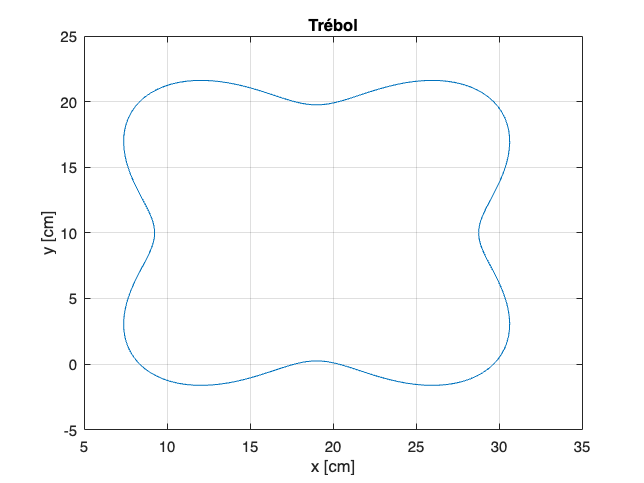

N = length(t1); 
data = zeros(N, 2);
for i = 1:N
    result = eval(subs(pos, [theta1, theta2], [t1(i), t2(i)])); 
    data(i, :) = result(1:2)'; 
end 

plot(data(:, 1), data(:, 2));
grid on; 
xlabel("x [cm]");
ylabel("y [cm]");
title("Trébol"); 

## Datos finales

Se guardan los datos en un **.mat **y se imprimen los datos como vector .txt que el spline de simcape pueda leer. 

referenceCurve = data ; 
save("data/trebolspline.mat", "referenceCurve"); 

for i = 1:size(data)
    disp(num2str(referenceCurve(i, 1)) + "," + num2str(referenceCurve(i, 2))+ ";")
end 

9.2467,10;
9.2323,9.693;
9.1895,9.3828;
9.1195,9.066;
9.0243,8.7398;
8.9068,8.4014;
8.7703,8.0486;
8.6188,7.6795;
8.4568,7.293;
8.2894,6.8883;
8.1216,6.4654;
7.959,6.025;
7.8068,5.5683;
7.6705,5.0973;
7.5552,4.6145;
7.4658,4.123;
7.4066,3.6265;
7.3815,3.1289;
7.3939,2.6346;
7.4464,2.1482;
7.5408,1.6744;
7.6783,1.218;
7.8593,0.78363;
8.0833,0.37567;
8.3492,-0.0017624;
8.655,-0.34497;
8.9982,-0.6508;
9.3757,-0.91666;
9.7836,-1.1407;
10.218,-1.3217;
10.6744,-1.4592;
11.1482,-1.5536;
11.6346,-1.6061;
12.1289,-1.6185;
12.6265,-1.5934;
13.123,-1.5342;
13.6145,-1.4448;
14.0973,-1.3295;
14.5683,-1.1932;
15.025,-1.041;
15.4654,-0.87836;
15.8883,-0.71061;
16.293,-0.54317;
16.6795,-0.38123;
17.0486,-0.22973;
17.4014,-0.093201;
17.7398,0.024347;
18.066,0.11948;
18.3828,0.18946;
18.693,0.23226;
19,0.24667;
19.307,0.23226;
19.6172,0.18946;
19.934,0.11948;
20.2602,0.024347;
20.5986,-0.093201;
20.9514,-0.22973;
21.3205,-0.38123;
21.707,-0.54317;
22.1117,-0.71061;
22.5346,-0.87836;
22.975,-1.041;
23.43